**Author:    Michal Szabo**

**Date:        10.12.2021**

# Practice 4. Optimal Estimation

## Activity 1. State estimation (Kalman filter)

Let us consider a water tank that can be modeled through the following equation


$$\frac{\textrm{dV}\left(t\right)}{\textrm{dt}}=q_{\textrm{in}} \left(t\right)-q_{\textrm{out}} \left(t\right)$$


where $V\left(t\right)$ is the tank volume, $q_{\textrm{in}} \left(t\right)$ is the output flow by pump and $q_{\textrm{out}} \left(t\right)$ is the output flow controllerd by a valve. The input flow provided by the pump is controlled through the voltage $v_h \left(t\right)$ according to $q_{\textrm{in}} \left(t\right)=k_b v_b \left(t\right)$. On the other hand, the output flow $q_{\textrm{out}} \left(t\right)$ through valve is given by $q_{\textrm{out}} \left(t\right)=k_v V\left(t\right)\ldotp$

Considering that the system parameters are $k_b =2$ and $k_v =0\ldotp 1$ , we want to the problem of states estimation using optimization. In particular, the tank volume $V$ should be estimated using the input voltage $v_b$ and the output flow measurement $q_{\textrm{out}}$ when there is a noncontrolled system noise (disturbance) $w_k$ (Gaussian with zero mean and variance equal to $Q=0\ldotp 1$) and a non-controlled measurement noise $k_v$ (Gaussian with zero mean and variance equal to $R=0\ldotp 1$). The value of $N=100$ input voltages ($v_b \left(k\right)$) and output flows ($q_{\textrm{out}} \left(k\right)$) are acquired with a sampling time equal to $T=1s$. They can be generated as indicated in the guide of the lab. Use as initial conditions of the state estimation filter:$\hat{V_1 } =10$ and $P_1 =0\ldotp 2$.

### 1.a - Problem formulation and Data generation

% Problem formulation
T=1; % sample time
kv=0.1; % parameter kv
kb=2; % parameter kb
A=exp(-kv*T); % parameter a (using exact discretization)
B=(1-exp(-kv*T))*kb/kv; % parameter b (using exact discretization)
C=kv; % parameter c
D=0; % parameter d

For calculation of Pareto plot we change the variance *Q* and then *R* using a for loop. Here we also define initial conditions.

p = 0;
% for e = 0.1:0.1:2
p=p+1; % index for pareto plot

Q=0.1; % variance of system noise (disturbance)
R=0.1; % variance of measurement noise
x1=10;P1=0.2; % Initial conditions from estimation 

We generate data with 100 data points but only one time because we don't want to work with different data all the time. The data are generated using the following functions:


$$x\left(k+1\right)=A\cdot x\left(k\right)+B\cdot u\left(k\right)+w\left(k\right)$$



$$y\left(k\right)=C\cdot x\left(k\right)+D\cdot u\left(k\right)+v\left(k\right)$$


% % Generating data
% rng(5); % initializing seed for random numbers
% N=100; % number of data points
% u=ones(N,1); % input vector
% x=zeros(N+1,1); % initialization of states
% y=zeros(N,1); % initialization of outputs
% x(1)=x1; % initial condition
% for k=1:N % data generation
%     x(k+1)=a*x(k)+b*u(k)+randn(1)*sqrt(Q); % state
%     y(k)=c*x(k)+d*u(k)+randn(1)*sqrt(R); % output
% end
% data=[u x(1:N) y];
% save data2 data; % saving data (don't save x(N+1)

### Kalman filter via numerical optimization

From saved data we extract our input $u$ and output $y\ldotp$

% Estimating x(N+1) from x(1:N) and u(1:N)
load data1;     % load data u,x,y (only uses u and y)
N=size(data,1); % determine the number of points
u=data(:,1);    % read the inputs
y=data(:,3);    % read the outputs

Then we formulate our optimization of the prediction problem using the following minimization function.

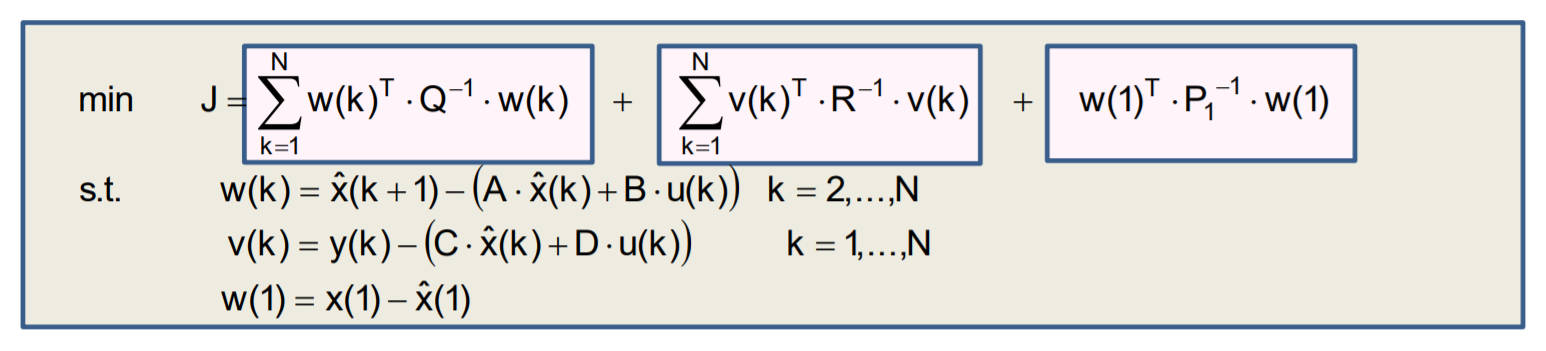

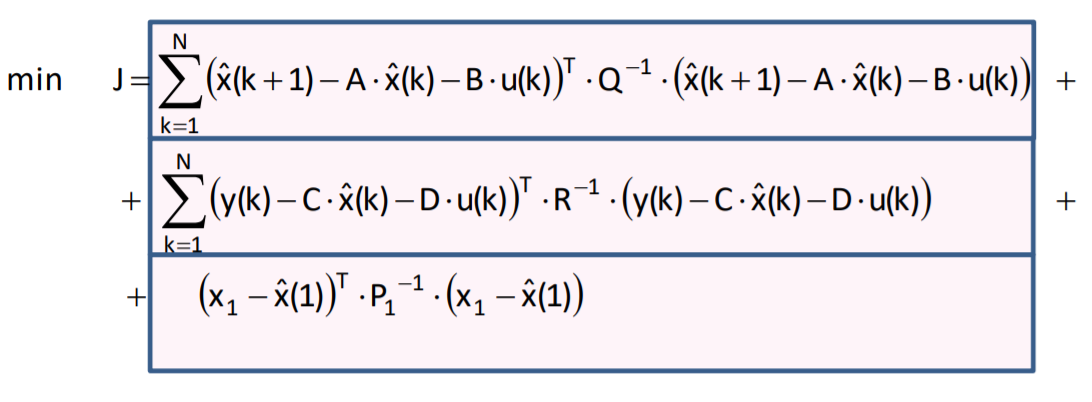

To introduce this problem to *yalmip * which will solve it numerically, we initialize variable $x$ and define our objective function and constraints.

x = sdpvar(repmat(1,1,N+1),repmat(1,1,N+1));
objective = (x1-x{1})'*P1^(-1)*(x1-x{1}); % disturbance
constraints = [];
for k = 1:N
    objective = objective+...
    (x{k+1}-A*x{k}-B*u(k))'*Q^(-1)*(x{k+1}-A*x{k}-B*u(k))...
    +(y(k)-C*x{k})'*R^(-1)*(y(k)-C*x{k});
end

And finally we solve the problem using *quadprog* solver and y*almip*.

options = sdpsettings('solver','quadprog');
optimize(constraints,objective,options);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


We extract the value of estimated state

x_est = zeros(N+1,1);
for k = 1:N+1
    x_est(k,1) = value(x{k});
end

And plot the result but only for $Q=0\ldotp 1$, other values are only used for calculation of pareto plot.

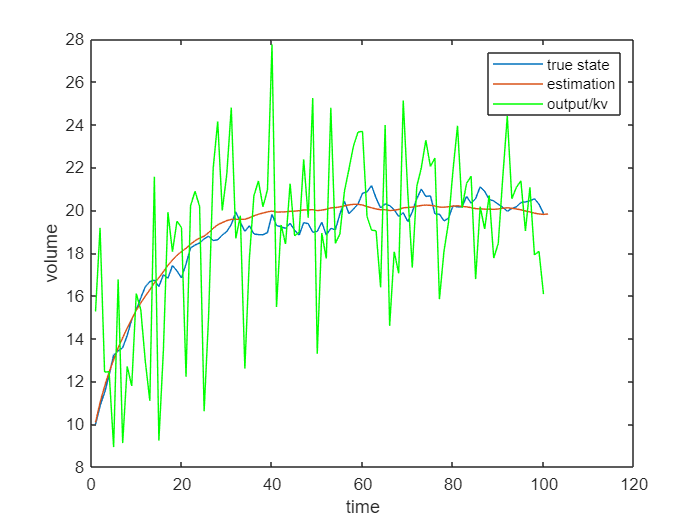

if Q == 0.1 && R == 0.1
    x_est_a = x_est;
    figure
    plot(data(:,2));hold on
    plot(x_est)
    plot(y/kv,'g')
    legend('true state','estimation','output/kv')
    xlabel('time')
    ylabel('volume')
end

To calculate Pareto plot we use the following equations

Where $w\left(k\right)$ is the system noise and $v\left(k\right)$ is the measurement noise regarding the state.

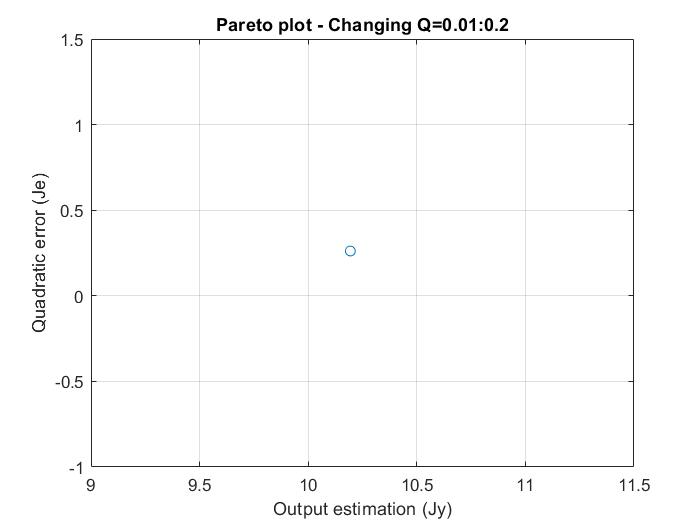

Je=0;
Jy=0;
for k=1:N
    w(k)=x_est(k+1)-(A*x_est(k)+B*u(k));    % System noise (disturbance)
    v(k)=y(k)-(C*x_est(k)+D*u(k));          % Measurement noise
    Je = Je + w(k)'*w(k);   % Quadratic error
    Jy = Jy + v(k)'*v(k);   % Output estimation
end

all_Je(p) = Je;
all_Jy(p) = Jy;

% end % end of for loop for pareto plot
figure
plot(all_Jy,all_Je,'o:')
title('Pareto plot - Changing Q=0.01:0.2')
xlabel('Output estimation (Jy)')
ylabel('Quadratic error (Je)')
grid on

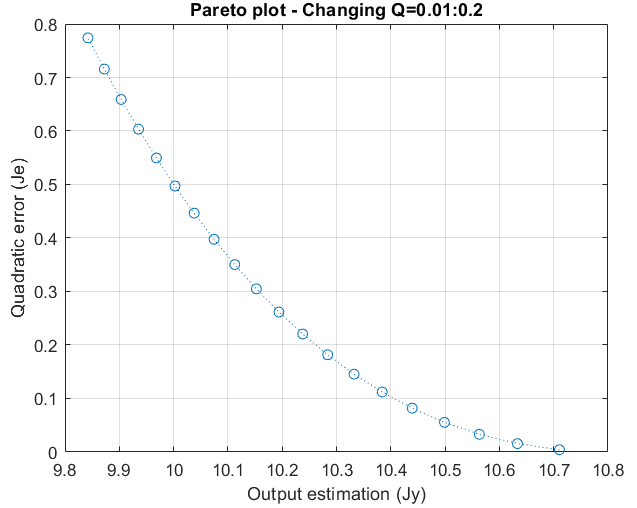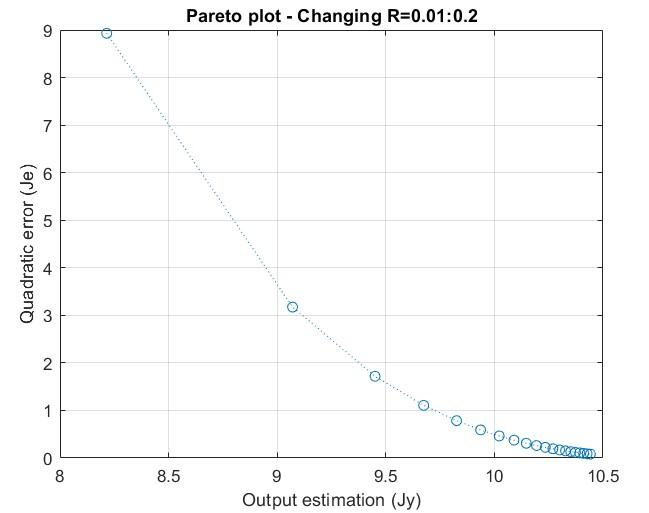

On both of these Pareto plots we can see that with increasing system error we have better output estimation and vice versa. That's why we need to find an optimal value of Q and R that will fit our requirements.

### 1.b - Kalman filter with 98% confidence interval

To calculate the the analytical solution we use Kalman filter. The equations for Kalman filter are the following

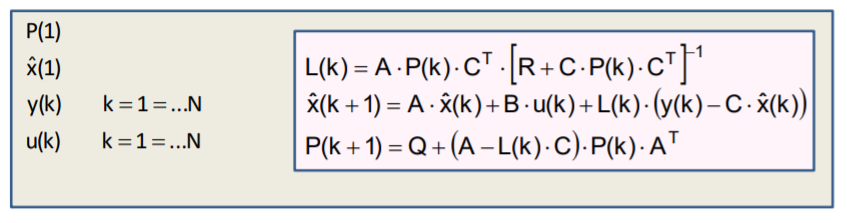

And then the confidence interval is defined by upper and lower bound with the following equations.


$$\mathrm{lb}\left(k\right)=x\left(k\right)-\alpha \cdot \sqrt{P\left(k\right)}$$



$$\mathrm{ub}\left(k\right)=x\left(k\right)+\alpha \cdot \sqrt{P\left(k\right)}$$


Where *alpha *defines our confidence interval and for 98% $\alpha =3$.

x=zeros(N+1,1);     % initialization of states
P=zeros(N+1,1);     % initialization of P matrix
L=zeros(N,1);       % initialization of L matrix
lb=zeros(N+1,1);    % lower bounds of states
ub=zeros(N+1,1);    % upper bounds of states
% For 98% -> alpha=3; for 95% -> alpha=2
alpha=3;    % select according confidence interval

p = 0;
for e = 0.1:0.1:2
p=p+1; % index for pareto plot

Q=0.1*e;    % controll system noise variance
R=0.1;      % measurement noise variance

x(1)=x1;    % initial condition for x;
P(1)=P1;    % initial condition for P;
lb(1)=x(1)-sqrt(P(1))*alpha*0.98;
ub(1)=x(1)+sqrt(P(1))*alpha*0.98;

for k=1:N   % codifying Kalman filter in Matlab
    L(k)=A*P(k)*C'/(R+C*P(k)*C');
    x(k+1)=A*x(k)+B*u(k)+L(k)*(y(k)-C*x(k));
    P(k+1)=Q+(A-L(k)*C)*P(k)*A';

    lb(k+1)=x(k+1)-alpha*sqrt(P(k+1));  % lower bound
    ub(k+1)=x(k+1)+alpha*sqrt(P(k+1));  % upper bound
end

Displaying the graphs with Q and R equaled to 0.1

if Q == 0.1 && R == 0.1
    x_kal = x;
    figure
    plot(x,'r'),hold on; % plot state estimation
    plot(lb,'b'); % plot lower bounds interval
    plot(ub,'b'); % plot upper bound interval
    plot(data(:,2),'k')
    title('Kalman filter: Estimation with 98% confidence')
    xlabel('time')
    ylabel('volume')
    
    figure
    plot(x_est_a,'r'), hold on
    plot(x,'g')
    plot(data(:,2),'k')
    legend('Numerical','Kalman','Real')
    title('Comparison of Numerical and Analytical solution')
    xlabel('time')
    ylabel('volume')
end

Calculating the Pareto plot for Kalman filter.

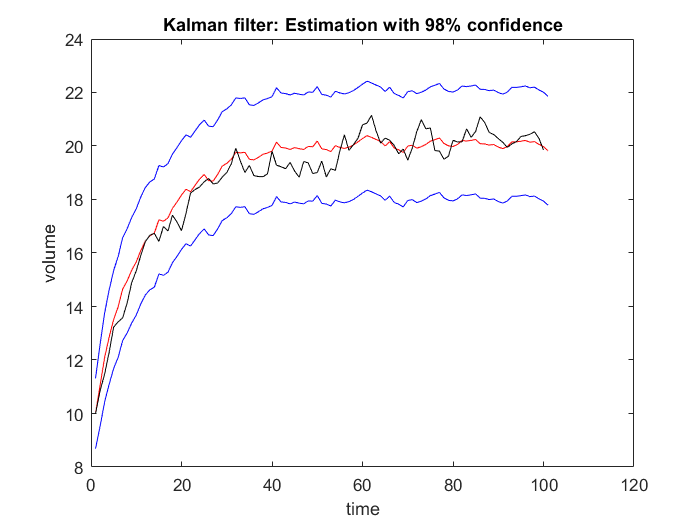

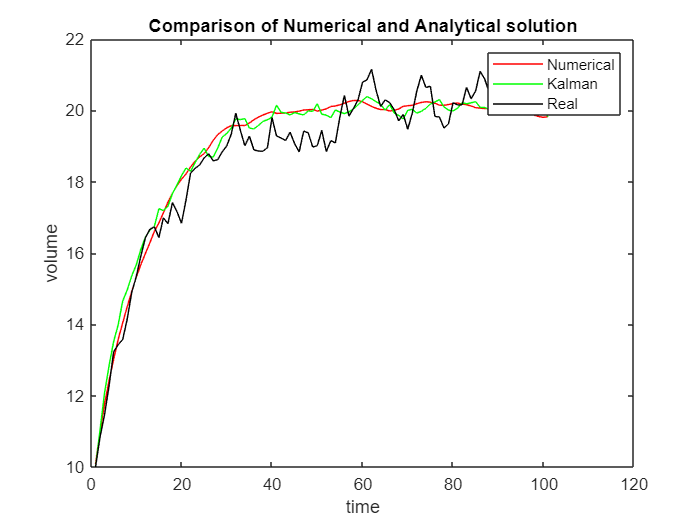

Je=0;
Jy=0;
for k=1:N
    w(k)=x(k+1)-(A*x(k)+B*u(k));    % System noise (disturbance)
    v(k)=y(k)-(C*x(k)+D*u(k));      % Measurement noise
    Je = Je + w(k)'*w(k);   % Quadratic error
    Jy = Jy + v(k)'*v(k);   % Output estimation
end

all_Je_A(p) = Je;
all_Jy_A(p) = Jy;

end % end of for loop for pareto plot

On this graph we can see red line which is estimated state by Kalman and blue lines represent upper and lower bound.

Comparing tha analytical Kalman solution and numerical using quadprog, we can see that they are quite similar. The Kalman filter looks a bit smoother than a state estimated numerically

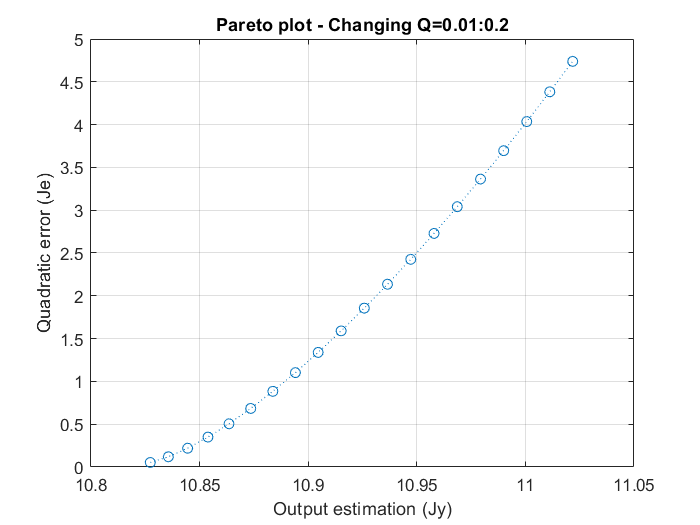

figure
plot(all_Jy_A,all_Je_A,'o:')
title('Pareto plot - Changing Q=0.01:0.2')
xlabel('Output estimation (Jy)')
ylabel('Quadratic error (Je)')
grid on

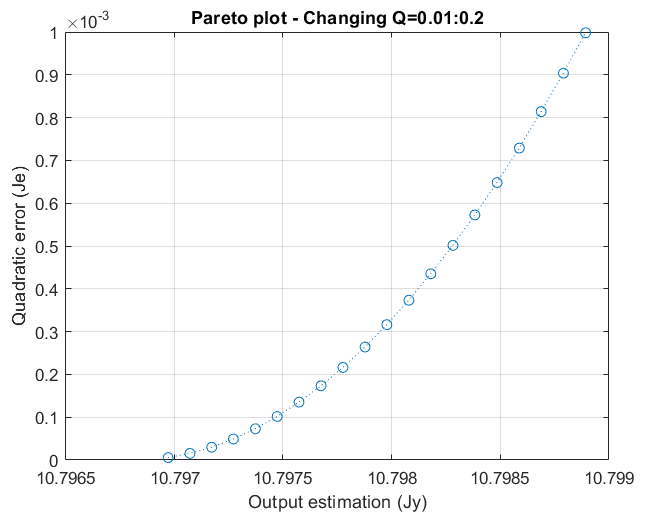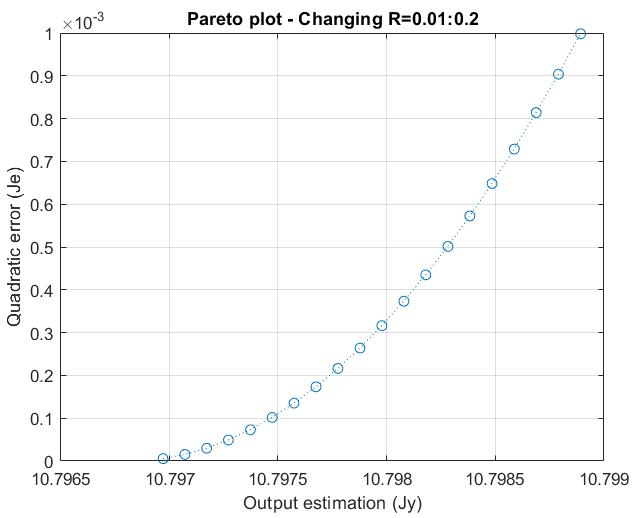

On the Pareto plots for the Kalman filter we can see different correlation between quadratic error and output estimation. Higher the quadratic error is, higher the output estimation error is and vice versa.

### 1.c - Steady-State Kalman

To calculate the steady-state Kalman we needed to solve the following equation to find P.

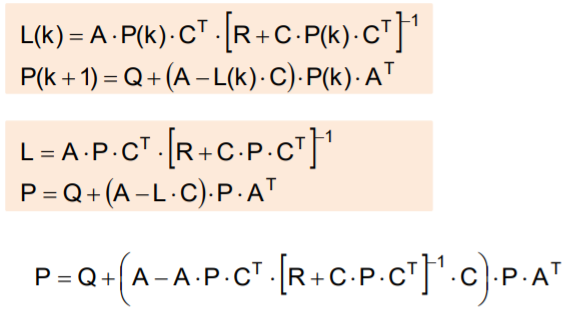

We substituted L in P with its equation and found 2 possible solutions.

% variance
Q=0.1;
R=0.1;

A=exp(-kv*T);   % parameter a (using exact discretization)
C=kv;           % parameter c

syms z
z=vpa(solve(z==Q+(A-A*z*C'*inv(R+C*z*C')*C)*z*A',z,'Real',true))

$$z = \left(\begin{array}{c} -2.1729057180862011395865087288967\\ 0.46021324886601872041966785430985 \end{array}\right)$$

We are gonna pick the one that is positive, because that is the correct one for us.

PSS=z(2)

$$PSS = 0.46021324886601872041966785430985$$

And with the PSS we are able to calculate our steady-state gain LSS.

LSS=A*PSS*C*(R+C*PSS*C)^-1

$$LSS = 0.39809720695226966940828200508746$$

Now we can calculate all the states using constants PSS and LSS.

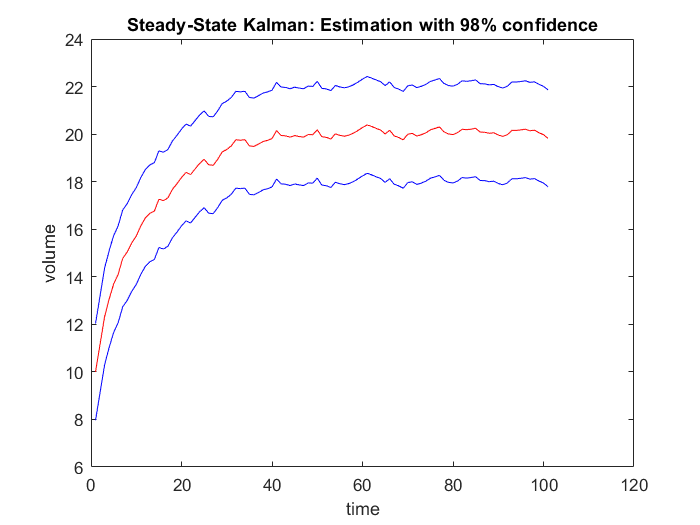

% Kalman filter with confidence interval using steady state
xss=zeros(N+1,1); % initialization of states
lbss=zeros(N+1,1); % lower bounds of states
ubss=zeros(N+1,1); % upper bounds of states
alpha=3; % choose the desired confidence
xss(1)=x1; % initial condition for x;
lbss(1)=x(1)-alpha*sqrt(PSS);
ubss(1)=x(1)+alpha*sqrt(PSS);

for k=1:N % codifying steady state Kalman filter
    xss(k+1)=A*xss(k)+B*u(k)+LSS*(y(k)-C*xss(k));
    lbss(k+1)=xss(k+1)-alpha*sqrt(PSS);
    ubss(k+1)=xss(k+1)+alpha*sqrt(PSS);
end

figure
plot(xss,'r'); % plot state estimation
hold on;
plot(lbss,'b'); % plot lower bounds interval
plot(ubss,'b'); % plot upper bound interval
title('Steady-State Kalman: Estimation with 98% confidence')
xlabel('time')
ylabel('volume')

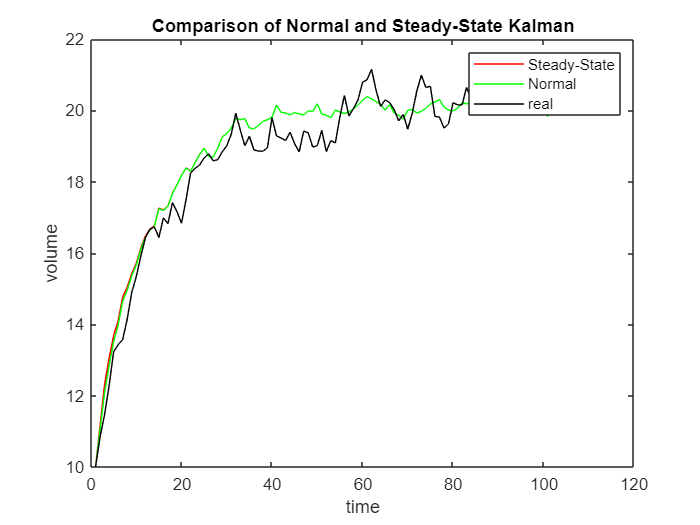

figure
plot(xss,'r'), hold on;
plot(x_kal,'g');
plot(data(:,2),'k');
legend('Steady-State','Normal','real')
title('Comparison of Normal and Steady-State Kalman')
xlabel('time')
ylabel('volume')

When comparing the Normal Kalman with changing P and L and Steady-State Kalman we can see that they are very similar, almost the same even if the the Steady-State Kalman uses constant PSS and LSS. We can also see that the biggest difference is in the beggining when the P and L are still changing but after some time they become constant.

Steady state Kalman with MATLAB function

% MATLAB Kalman function
SYS=ss(A,[B 1],C,[0 0],-1);
[KEST,L,P] = kalman(SYS,Q,R,'delayed')

KEST =
 
  A = 
          x1_e
   x1_e  0.865
 
  B = 
             u1      y1
   x1_e   1.903  0.3981
 
  C = 
         x1_e
   y1_e   0.1
   x1_e     1
 
  D = 
         u1  y1
   y1_e   0   0
   x1_e   0   0
 
Input groups:              
       Name        Channels
    KnownInput        1    
    Measurement       2    
                           
Output groups:                
         Name         Channels
    OutputEstimate       1    
    StateEstimate        2    
                              
Sample time: unspecified
Discrete-time state-space model.



L = 0.3981

P = 0.4602

Using the kalman MATLAB function we get the same results of PSS and gain LSS as in our steady-state Kalman.

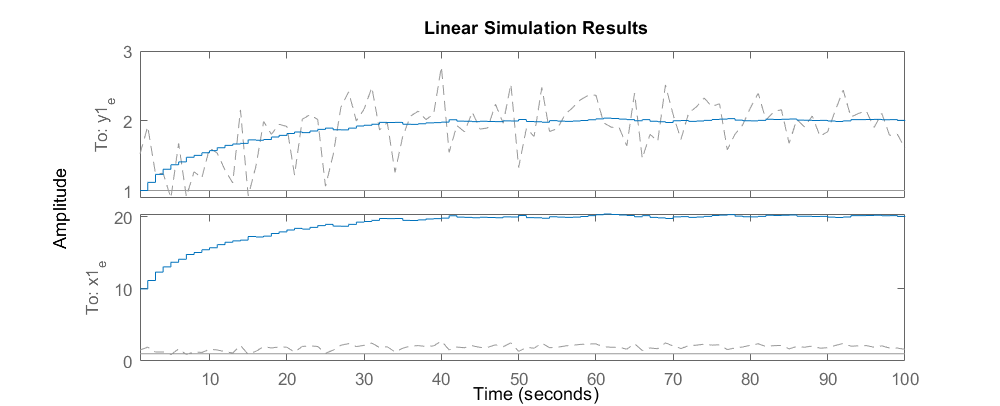

figure('Position',[0 0 1200 400])
lsim(KEST,[u,y],1:100,x1)

### 1.d - Steady state Kalman filter using LQR LMIs and Duality

 Firsrt we initialize our system variables.

T=1; % sample time
kv=0.1; % parameter kv
kb=2; % parameter kb
a=exp(-kv*T); % parameter a (using exact discretization)
b=(1-exp(-kv*T))*kb/kv; % parameter b (using exact discretization)
c=kv; % parameter c
d=0; % parameter d
Q=0.1; % deviation of system noise (disturbance)
R=0.1; % deviation of measurement noise

We define our matrices, objective function and constraints. The optimal value of LSS can be found solving the ricatti equation for the LQR that is formulated as LMI and constrained as on the following image.

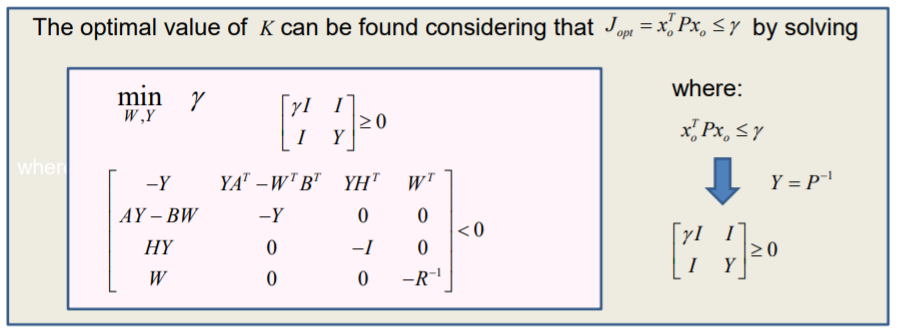

%LMI solution
A=a'; % Duality principle for observer design
B=c'; % Duality principle for observer design
Y = sdpvar(1,1);
W = sdpvar(1,1);
gamma=sdpvar(1,1);
H=sqrt(Q);
F = [Y >= 0];
F = [F, [gamma*eye(1) eye(1);eye(1) Y]>=0];
F = [F, [  -Y      Y*A'-W'*B'    Y*H'      W';
         A*Y-B*W      -Y          0         0;
           H*Y         0         -1         0;
            W          0          0    -R^(-1)]  <=  0];

% Solving the problem
options = sdpsettings('solver', 'sedumi');
optimize(F,gamma,options)

SeDuMi 1.3.5 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 3, order n = 8, dim = 22, blocks = 3
nnz(A) = 9 + 0, nnz(ADA) = 7, nnz(L) = 5
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.66E+01 0.000
  1 :  -1.04E+00 1.39E+00 0.000 0.0838 0.9900 0.9900   1.38  1  1  2.1E+00
  2 :  -6.47E-01 7.36E-01 0.000 0.5297 0.9000 0.9000   1.56  1  1  1.5E+00
  3 :  -4.77E-01 3.25E-01 0.000 0.4412 0.9000 0.9000   1.31  1  1  6.8E-01
  4 :  -4.49E-01 1.02E-01 0.000 0.3133 0.9000 0.9000   1.20  1  1  1.9E-01
  5 :  -4.54E-01 2.90E-02 0.000 0.2854 0.9000 0.9000   1.09  1  1  5.1E-02
  6 :  -4.57E-01 8.72E-03 0.000 0.3003 0.9000 0.9000   1.03  1  1  1.5E-02
  7 :  -4.59E-01 2.62E-03 0.000 0.3002 0.9000 0.9000   1.01  1  1  4.4E-03
  8 :  -4.60E-01 7.29E-04 0.000 0.2784 0.9000 0.9000   1.00  1  1  1.2E-03
  9 :  -4.60E-01 1.79E-04 0.000 0.2460 0.9000 0.9000   1.00  1  1  3.0E-04
 10 :  -4.60E-01 3.81

ans = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.11.0.1769968 (R2021b)'
       yalmiptime: 0.0536
       solvertime: 0.1134
             info: 'Successfully solved (SeDuMi-1.3)'
          problem: 0


LSS_lqr = (value(W)*inv(value(Y)))' % Duality principle for observer design

LSS_lqr = 0.3981

We can see that this gain calculated using LMI LQR method is the same as the gain calculated by Steady-State Kalman and MATLAB Kalman function.

### 1.e - Moving Horizon Estimation (MHE) via numerical optimization

In MHE we are considering limited data points for estimation in our case N=10.clc, clear

% formulation of the optimization problem
N=10; % determine the number of points
x_hat = sdpvar(repmat(1,1,N+1),repmat(1,1,N+1));
x_0=sdpvar(1,1);
yd=sdpvar(N,1);
ud=sdpvar(N,1);

We set our matrices and our objective function using the same minimization function as before.

A=a;
B=b;
C=c;
Q=0.1;
R=0.1;

objective = (x_0-x_hat{1})'*P1^(-1)*(x_0-x_hat{1});
constraints = [];
for k = 1:N
    objective = objective+...
    (x_hat{k+1}-A*x_hat{k}-B*ud(k))'*Q^(-1)*(x_hat{k+1}-A*x_hat{k}-B*ud(k))...
    +(yd(k)-C*x_hat{k})'*R^(-1)*(yd(k)-C*x_hat{k});
end

We create our estimator of the state which we will use to perdict each state by only looking at N points.

options = sdpsettings('solver','quadprog');
estimator=optimizer(constraints,objective,options, {yd,ud,x_0},x_hat{N+1});

We define fisrt 11 states using the estimation from exercise 1.a in order to calculate other states, because we have to look at the state that is k-N, and the fisrt state we can calculate with MHE method and with control horizon of 10 points is x_est_mhe(12).

M=100; % Estimation time
x_est_mhe=zeros(M+1,1); % initialization of states
%initialize the first N state estimation using the result of exercise (a)
x_est_mhe(1:11)=x_est(1:11);
% run the MHE in real time
for k=N+1:M+1
 x_est_mhe(k+1)=estimator(y(k-N:k-1),u(k-N:k-1),x_est_mhe(k-N));
end

Displaying the results.

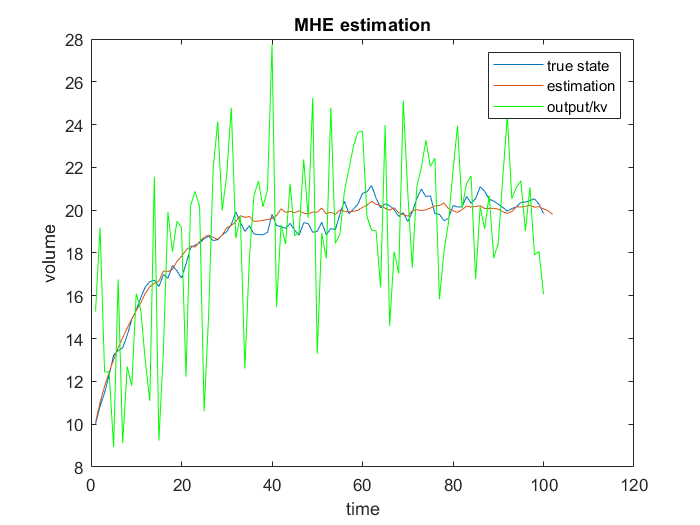

figure
plot(data(:,2));hold on
plot(x_est_mhe)
plot(y/kv,'g')
title('MHE estimation')
legend('true state','estimation','output/kv')
xlabel('time')
ylabel('volume')

MHE is also quite precise state estimation even if we do not consider all the known values to estimate the state.

## Activity 2: Parameter Estimation

In order to estimate the parameters of the pump $k_b$ and valve $k_v$ , input and output data is collected using a sampling time $T=0\ldotp 2s$ generated as indicated in the guide of the lab. Considering that the model (1) is discretized using the Euler model.

We first generate and save the data.

% Data generation
rng(5) % Inizialize random seed (for repetitibility)
T=0.2; % Sample time
kv=0.1;kb=2; % parameters for data generation
A=-kv;B=kb;sys=ss(A,B,1,0); % continuous system sys:dx=A·x+B·u
% y=1·x+0·u
% y=x=V=volume (Output = State variable)
% u=v_b (Input variable)
dsys=c2d(sys,T); % it converts to discrete system
[nd,dd]=tfdata(dsys,'v'); % it returns numerator and denominator
% as vectors
b=nd(2);a=-dd(2); % x(k)=a·x(k-1)+b·u(k)
N=500; % Number of input/output patterns
y=zeros(N,1); % it inizializes vector y (ouputs)
u=ones(N,1); % it inizializes vector u (inputs)
sigma=0.2; % Deviation of the white noise

% % Generating and saving data
% for k=2:N % We obtain the data adding WHITE NOISE
%  y(k)=a*y(k-1)+b*u(k-1)+sigma*randn(1);
% end
% data=[u y];
% save data data % Save data for future calculations

Displaying our generated data.

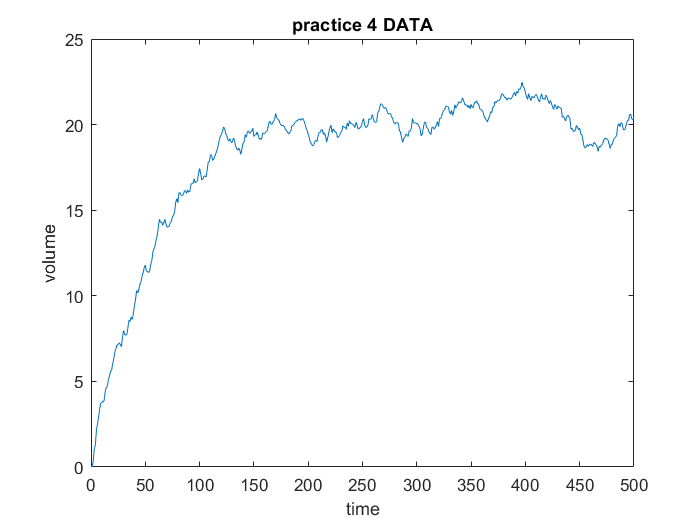

load data2
u=data(:,1);    % it extracts inputs
y=data(:,2);    % it extracts outputs

figure
plot(y) % Plot the data generated
title('practice 4 DATA')
xlabel('time')
ylabel('volume')

### 2.a - Estimating $k_b$ and $k_v$ using quadprog solver with and without constraints

Without contstraints:

Y=y(2:N);               % column matrix Y
C=[y(1:N-1) u(1:N-1)];  % matrix C

%Numerical Optimization
J = @(x)(Y-C*x)'*(Y-C*x);       % performance index
theta_est=fminsearch(J,[0;0]);  % parameters estimators from numerical

theta = sdpvar(2,1);
objective= (Y-C*theta)'*(Y-C*theta); % performance index
constraints=[];
options = sdpsettings('solver','quadprog');
optimize(constraints,objective,options); % numerical optimization


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


theta_est = value(theta)

theta_est =     0.9818
    0.3710


theta_est_2=(C'*C)\C'*Y    % another way to obtain theta_est

theta_est_2 =     0.9818
    0.3710


kv_est = (1-theta_est(1))/T %Estimation of kv (Euler approximation)

kv_est = 0.0908

kb_est = theta_est(2)/T %Estimation of kb (Euler approximation) 

kb_est = 1.8548

With constraints:

Y=y(2:N);               % column matrix Y
C=[y(1:N-1) u(1:N-1)];  % matrix C

%Numerical Optimization
J = @(x)(Y-C*x)'*(Y-C*x);       % performance index
theta_est_con=fminsearch(J,[0;0]);  % parameters estimators from numerical

theta = sdpvar(2,1);
objective= (Y-C*theta)'*(Y-C*theta); % performance index
constraints=[Y-C*theta<=0.56];
options = sdpsettings('solver','quadprog');
optimize(constraints,objective,options); % numerical optimization


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


theta_est_con = value(theta);
kv_est_con = (1-theta_est_con(1))/T % Estimation of kv (Euler approximation)

kv_est_con = 0.0908

kb_est_con = theta_est_con(2)/T     % Estimation of kb (Euler approximation) 

kb_est_con = 1.8548

We obtained the same value for non-constrained and constrained problem where $k_v =0\ldotp 0908$ and $k_b =1\ldotp 8548$. We used constraint $Y-C\cdot \theta \le 0\ldotp 56$. When we lover the value 0.56 the estimated parameters change.

### 2.b - Non recursive method

Here we estimate our parameters and their confidence intervals. Confidence intervals are defined by the following equations.

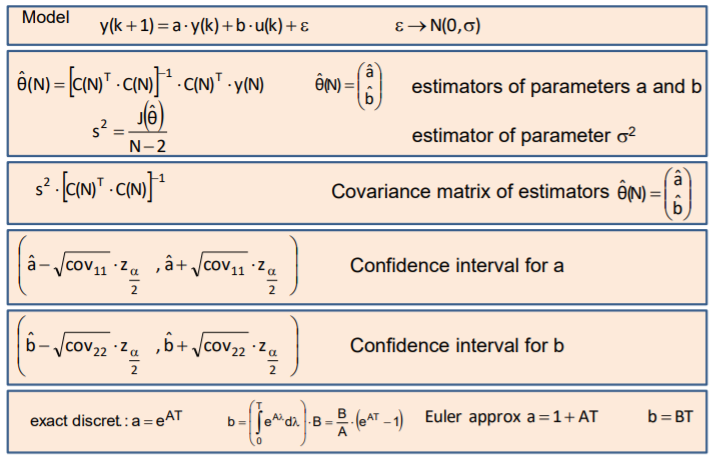

Where we are going to consider 98% confidence interval so alpha=3.

theta_est_3 = (C'*C)\C'*Y %non-recursive least squares formula

theta_est_3 =     0.9818
    0.3710


%Confidence intervals
sigma2=J(theta_est)/(N-2); % estimation of noise variance
sigma2b = sigma2; % saving variance for 2.d
Cov_mat=sigma2*(C'*C)'; % covariance matrix of the parameters estimators
std_error=sqrt(diag(Cov_mat)); % standard errors

kv_est=(1-theta_est(1))/T; % point l estimation of kv using Euler approximation
lbkv=(1-theta_est(1)-std_error(1)*3)/T; % lower bound for 98% confidence interval for kv
ubkv=(1-theta_est(1)+std_error(1)*3)/T; % upper bound for 98% confidence interval for kv
% Exact determination of confidence interval for kb_est is too difficult
kb_est=theta_est(2)/T; % point estimation of kb using Euler approximation
lbkb=(theta_est(2)-std_error(2)*3)/T; % lower bound for 98% confidence interval for kb
ubkb=(theta_est(2)+std_error(2)*3)/T; % upper bound for 98% confidence interval for kb

### Calculation using arx.

sys_arx = arx([y,u],[1,1,0])

sys_arx =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 0.9818 z^-1                           
                                                   
  B(z) = 0.371                                     
                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=1   nb=1   nk=0
   Number of free coefficients: 2
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data.         
Fit to estimation data: 95.43% (prediction focus)
FPE: 0.04074, MSE: 0.04025                       



[theta_est_ARX,theta_est_ARX_sd] = getpvec(sys_arx) %theta and standard deviation of theta

theta_est_ARX =    -0.9818
    0.3710


theta_est_ARX_sd =     0.0021
    0.0384


theta_est_ARX = abs(theta_est_ARX);
% Parameter nominal values and confidence interval
kv_est_ARX = (1 - theta_est_ARX(1)) / T;                     % point 1 estimation of kv using Euler approximation
lbkv_ARX = (1 - theta_est_ARX(1) - theta_est_ARX_sd(1)*3) / T;  % lower bound for 98% confidence interval for kv
ubkv_ARX = (1 - theta_est_ARX(1) + theta_est_ARX_sd(1)*3) / T;  % upper bound for 98% confidence interval for kv
% Exact determination of confidence interval for kb_est is too difficult
kb_est_ARX = theta_est_ARX(2) / T;                           % point estimation of kb using Euler approximation
lbkb_ARX = (theta_est_ARX(2) - theta_est_ARX_sd(2)*3) / T;      % lower bound for 98% confidence interval for kb
ubkb_ARX = (theta_est_ARX(2) + theta_est_ARX_sd(2)*3) / T;      % upper bound for 98% confidence interval for kb

We create a table to compare the results.

Comparison = ["kv";"lbkv";"ubkv";"kb";"lbkb";"ubkb"];
Non_recursive = [kv_est;lbkv;ubkv;kb_est;lbkb;ubkb];
ARX = [kv_est_ARX;lbkv_ARX;ubkv_ARX;kb_est_4;lbkb_ARX;ubkb_ARX];
results = table(Comparison,Non_recursive,ARX)

results = 6×3 table
    Comparison    Non_recursive      ARX   
    __________    _____________    ________

      "kv"          0.090754       0.090754
      "lbkv"         -1259.8       0.059997
      "ubkv"            1260        0.12151
      "kb"            1.8548         1.8548
      "lbkb"         -65.504         1.2795
      "ubkb"          69.213         2.4301


We can see in the table that the values of $k_v$ and $k_b$ are the same but the confidence intervals is different, smaller for the arx model which means its more precise or confident.

### 2.c - Recursive method

Recursive method is designed using the following equations.

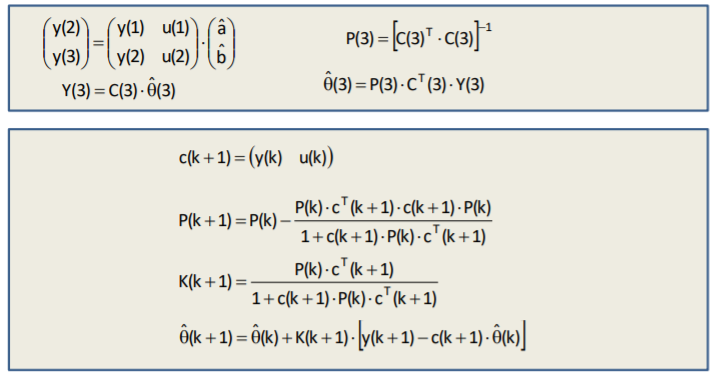

Y=[y(2);y(3)];          %Y(3)
C=[y(1:2) u(1:2)];      %C(3)
P=inv(C'*C);            %P(3)
theta_est_rec=P*C'*Y;    %theta(3)
for i=3:N-1
 c=[y(i) u(i)];
 D=1+c*P*c'; %Denominator
 K=P*c'/D;
 theta_est_rec=theta_est_rec+K*(y(i+1)-c*theta_est_rec);
 P=P-P*c'*c*P/D;
end

kv_est_rec=-log(theta_est_rec(1))/T % point estimation of kv

kv_est_rec = 0.0916

kb_est_rec=kv_est_rec*theta_est_rec(2)/(1-exp(-kv_est_rec*T)) % kb

kb_est_rec = 1.8718

clear lbkb ubkb lbkv ubkv kb_est kv_est;
lbkb=zeros(N,1);
ubkb=zeros(N,1);
lbkv=zeros(N,1);
ubkv=zeros(N,1);
kb_est=zeros(N,1);
kv_est=zeros(N,1);
for i=3:N-1
    c=[y(i) u(i)];

    D=1+c*P*c'; %Denominator
    K=P*c'/D;
    theta_est_rec=theta_est_rec+K*(y(i+1)-c*theta_est_rec);
    P=P-P*c'*c*P/D;

    sigma2=J(theta_est_rec)/(i-2);  % estimation of noise variance
    Cov_mat=sigma2*P;               % covariance matrix
    std_error=sqrt(diag(Cov_mat));  % standard errors
    
    kv_est(i)=(1-theta_est_rec(1))/T;               % point estimation of kv
    lbkv(i)=(1-theta_est_rec(1)-std_error(1)*3)/T;  % lower bound for 98%
    ubkv(i)=(1-theta_est_rec(1)+std_error(1)*3)/T;  % upper bound for 98%
    kb_est(i)=theta_est_rec(2)/T;                   % point estimation of kb
    lbkb(i)=(theta_est_rec(2)-std_error(2)*3)/T;    % lower bound for 98%
    ubkb(i)=(theta_est_rec(2)+std_error(2)*3)/T;    % upper bound for 98%
end

### Calculation using recursive arx

load data2 data; % Read data
u = data(:,1); % it extracts inputs
y = data(:,2); % it extracts outputs 
N = size(data,1); % determine the number of points
T = 0.2; % Sample time

lbkb_ARX1=zeros(N,1);
ubkb_ARX1=zeros(N,1);
lbkv_ARX1=zeros(N,1);
ubkv_ARX1=zeros(N,1);
kv_est_ARX=zeros(N,1);
kb_est_ARX=zeros(N,1);
std_error_ARX = [];

estimator = recursiveARX([1 1 0]);

for k = 1:N
    [theta1,theta2,y_hat] = estimator(y(k),u(k));
    cov = estimator.ParameterCovariance;  % covariance matrix
 
    theta_ARX = [-theta1(2) theta2];          
    std_error_ARX = diag(sqrt(cov));

    kv_est_ARX(k) =(1-theta_ARX(1))/T;                     % Estimation of kv
    lbkv_ARX1(k) = (1-theta_ARX(1)-std_error_ARX(1)*3)/T;   % lower bound for 98%
    ubkv_ARX1(k) = (1-theta_ARX(1)+std_error_ARX(1)*3)/T;   % upper bound for 98%

    kb_est_ARX(k) = theta_ARX(2)/T;                      % Estimation of kb
    lbkb_ARX1(k) = (theta_ARX(2)-std_error_ARX(2)*3)/T;   % lower bound for 98%
    ubkb_ARX1(k) = (theta_ARX(2)+std_error_ARX(2)*3)/T;   % upper bound for 98%
end

kv_est_ARX1=-log(theta_ARX(1))/T % point estimation of kv

kv_est_ARX1 = 0.0881

kb_est_ARX1=kv_est_ARX1*theta_ARX(2)/(1-exp(-kv_est_ARX1*T)) % kb

kb_est_ARX1 = 1.8056

Table for comparison.

Comparison = ["kv";"lbkv";"ubkv";"kb";"lbkb";"ubkb"];
recursive = [kv_est_rec;lbkv(N-2);ubkv(N-2);kb_est_rec;lbkb(N-2);ubkb(N-2)];
recARX = [kv_est_ARX1;lbkv_ARX1(N-2);ubkv_ARX1(N-2);kb_est_ARX1;lbkb_ARX1(N-2);ubkb_ARX1(N-2)];
results = table(Comparison,recursive,recARX)

results = 6×3 table
    Comparison    recursive     recARX  
    __________    _________    _________

      "kv"        0.091588      0.088148
      "lbkv"      0.067184     -0.062885
      "ubkv"       0.11148       0.23784
      "kb"          1.8718        1.8056
      "lbkb"        1.4119        -1.018
      "ubkb"        2.2413        4.5994


Comparing the recursive method and arx recursive method, we can see that the recursive ARX is now less precise then just recursive method, and the bound for recursive ARX are bigger.

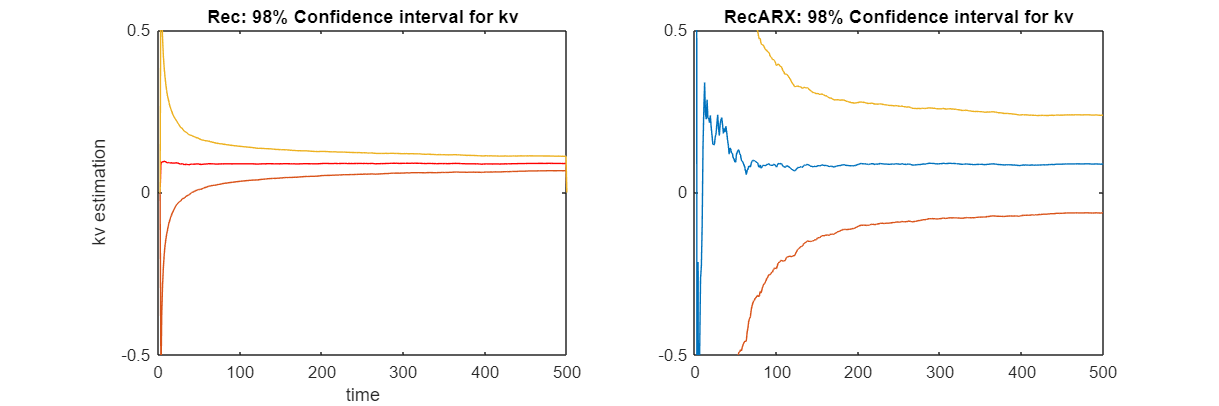

figure('Position',[0 0 1200 400])
subplot(1,2,1)
plot(kv_est,'r'), hold on;
plot(lbkv);
plot(ubkv);
axis([0 N -0.5 0.5]);
title('Rec: 98% Confidence interval for kv');
xlabel('time');
ylabel('kv estimation');
subplot(1,2,2)
plot(kv_est_ARX), hold on
plot(lbkv_ARX1)
plot(ubkv_ARX1)
title('RecARX: 98% Confidence interval for kv')
axis([0 N -0.5 0.5]);

Comparison of $k_v$ estimated using recursive method and recursiveARX.

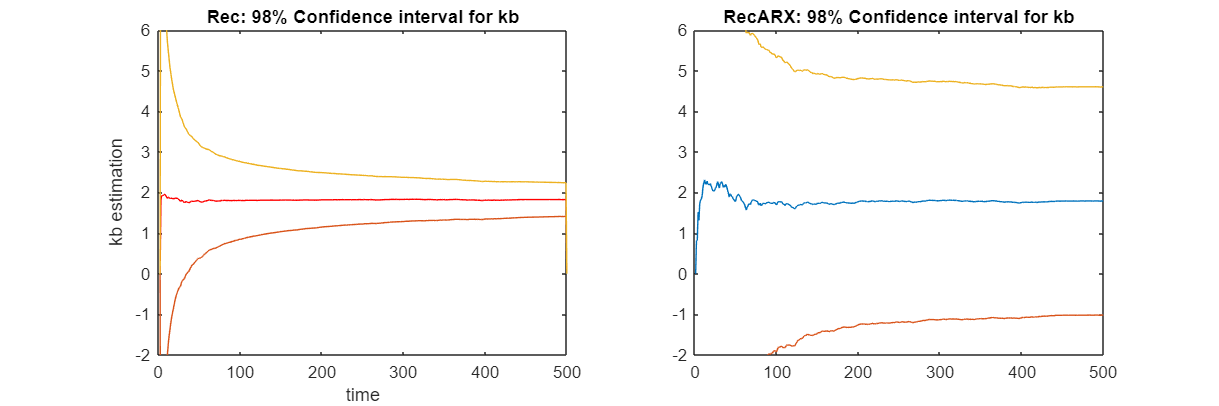

figure('Position',[0 0 1200 400])
subplot(1,2,1)
plot(kb_est,'r'), hold on;
plot(lbkb);
plot(ubkb);
axis([0 N -2 6]);
title('Rec: 98% Confidence interval for kb');
xlabel('time');
ylabel('kb estimation');
subplot(1,2,2)
plot(kb_est_ARX), hold on
plot(lbkb_ARX1)
plot(ubkb_ARX1)
title('RecARX: 98% Confidence interval for kb')
axis([0 N -2 6]);

Comparison of $k_b$ estimated using recursive method and recursiveARX.

### 2.d - Using Kalman filter as an estimator

% Parameter estimation
load data2                    % it reads data
u = data(:, 1);               % it extracts inputs
y = data(:, 2);               % it extracts outputs
N = 500;
T = 0.2;

Y = [y(2); y(3)];             % Y(3)
C = [y(1: 2) u(1: 2)];        % C(3)
P = inv(C' * C);              % P(3)
theta_est_kal = P * C' * Y;   % theta(3)

sigma2=sigma2b  % estimation of noise variance from 2.b

sigma2 = 0.0404


lbkb_kal=zeros(N, 1);
ubkb_kal=zeros(N, 1);
lbkv_kal=zeros(N, 1);
ubkv_kal=zeros(N, 1);
kbest_kal=zeros(N, 1);
kvest_kal=zeros(N, 1);

J = @(x) (Y-C*x)'*(Y-C*x);               % performance index

We designed our Kalman filter using the equations in the slides.

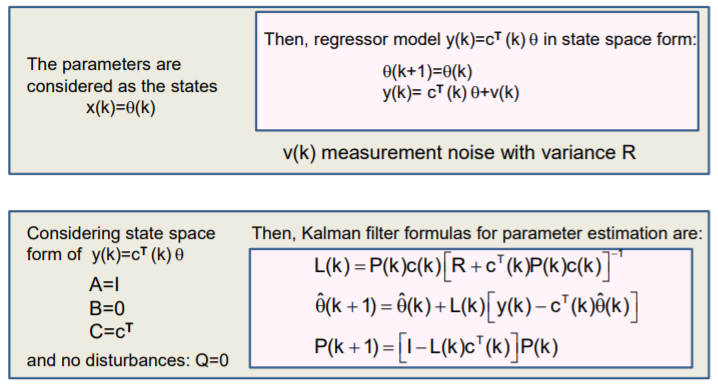

Considering that the output $y\left(k\right)$ is $y\left(k+1\right)$.

for i=3:N-1
    c=[y(i) u(i)]';         
    L=P*c/(sigma2+c'*P*c);
    theta_est_kal=theta_est_kal+L*(y(i+1)-transpose(c)*theta_est_kal);
    P=(eye(2)-L*transpose(c))*P;
        
    sigma2=J(theta_est_kal)/(i-2);      % estimation of noise variance
    Cov_mat=sigma2*P;                   % covariance matrix
    std_error=sqrt(diag(Cov_mat));      % standard errors

    kv_est_kal(i)=(1-theta_est_kal(1))/T;   % point estimation of kv
    lbkv_kal(i)=(1-theta_est_kal(1)-std_error(1)*3)/T;  % lower bound for 98%
    ubkv_kal(i)=(1-theta_est_kal(1)+std_error(1)*3)/T;  % upper bound for 98%

    kb_est_kal(i)=theta_est_kal(2)/T;       % point estimation of kb
    lbkb_kal(i)=(theta_est_kal(2)-std_error(2)*3)/T;    % lower bound for 98%
    ubkb_kal(i)=(theta_est_kal(2)+std_error(2)*3)/T;    % upper bound for 98%
end
kv_est_Kal1=-log(theta_est_kal(1))/T    % point estimation of kv

kv_est_Kal1 = 0.1006

kb_est_Kal1=kv_est_Kal1*theta_est_kal(2)/(1-exp(-kv_est_Kal1*T)) % kb

kb_est_Kal1 = 2.0596

The results using Kalman are very precise and similar to the initial parameters of $k_v =0\ldotp 1$ and $k_b =2$. This method looks to be the best for parameter estimation.

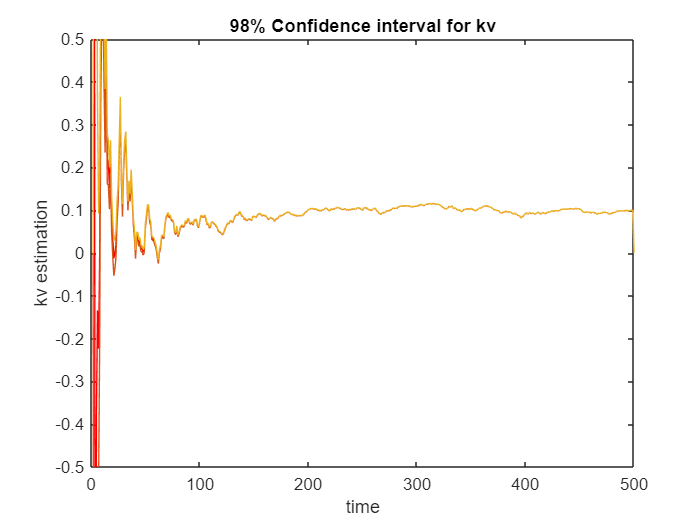

figure
plot(kv_est_kal,'r');
hold on;
plot(lbkv_kal);
plot(ubkv_kal);
axis([0 N -0.5 0.5]);
title('98% Confidence interval for kv');
xlabel('time');
ylabel('kv estimation');

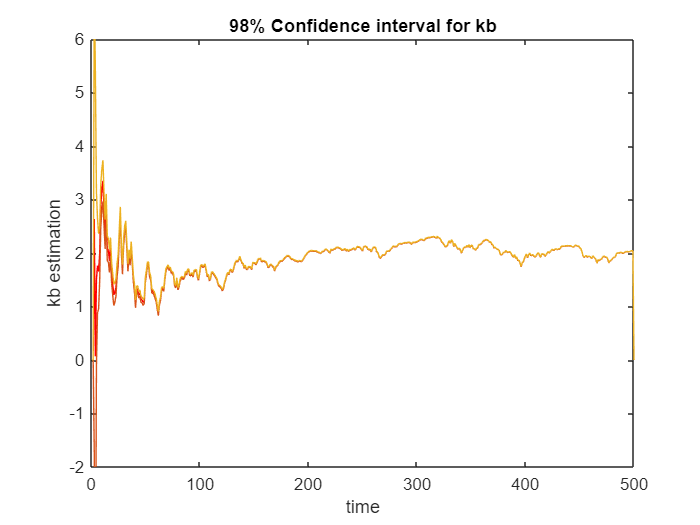

figure
plot(kb_est_kal,'r');
hold on;
plot(lbkb_kal);
plot(ubkb_kal);
axis([0 N -2 6]);
title('98% Confidence interval for kb');
xlabel('time');
ylabel('kb estimation');

On both graphs we can see that the confidence interval is really small which means that the estimated value is very close to the real value.